# **MATLAB for Image Processing **

Read images in Matlab

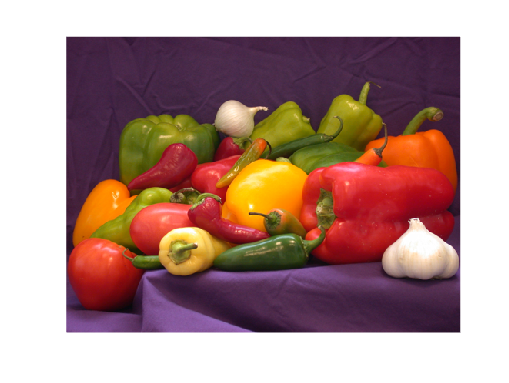

I=imread('peppers.png');
imshow(I)

size(I)

ans =    384   512     3


Write images in Matlab

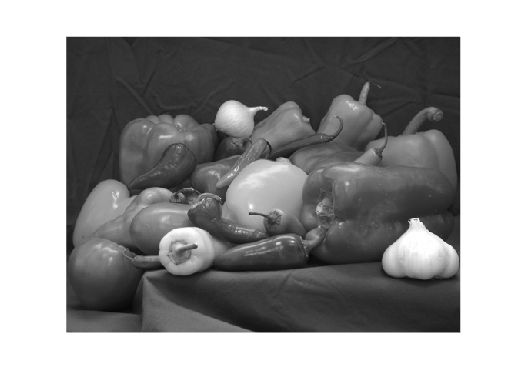

Igrey=rgb2gray(I);
imshow(Igrey)

imwrite(Igrey, 'cell_gray.tif', 'tiff')

Negative of Image

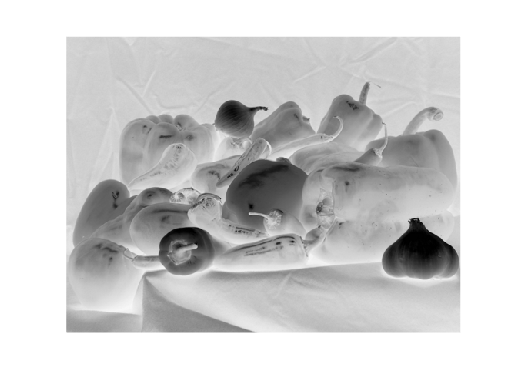

% levels of the 8-bit image
L = 2 ^ 8;    
% finding the negative                   
neg = (L - 1)-Igrey;
imshow(neg)

Logarithmic Transformation

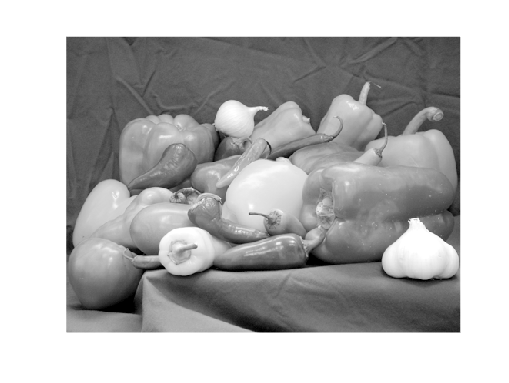

Ilog=2*log(double(Igrey));
imshow(Ilog,[6,11])

Brightness Modification

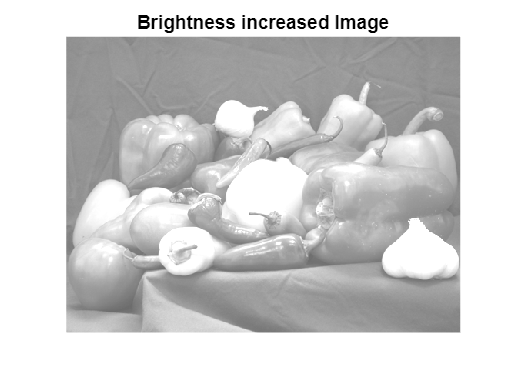

Ibright=Igrey+100;
imshow(Ibright)
title('Brightness increased Image')

Contrast Adjustment

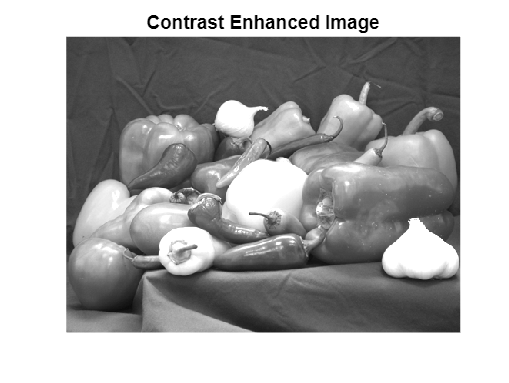

Icontr=Igrey*1.5;
imshow(Icontr)
title('Contrast Enhanced Image')

Bit Plane Slicing

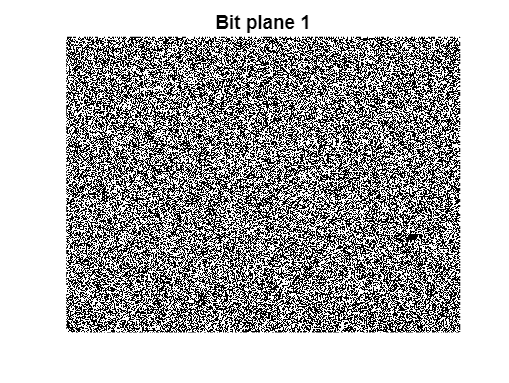

B=bitget(Igrey,1); figure, imshow(logical(B));title('Bit plane 1');

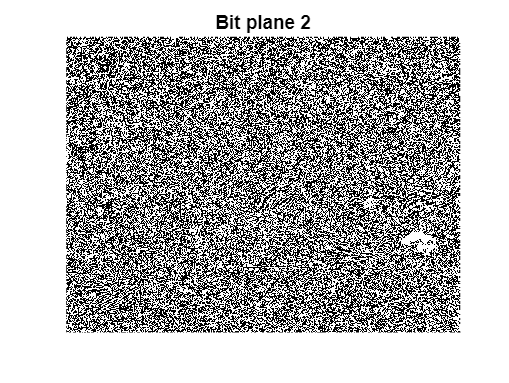

B=bitget(Igrey,2); figure, imshow(logical(B));title('Bit plane 2');

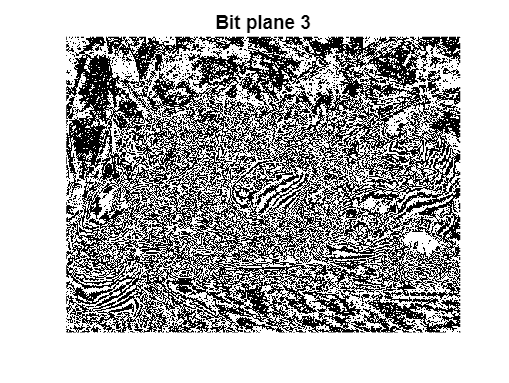

B=bitget(Igrey,3); figure, imshow(logical(B));title('Bit plane 3');

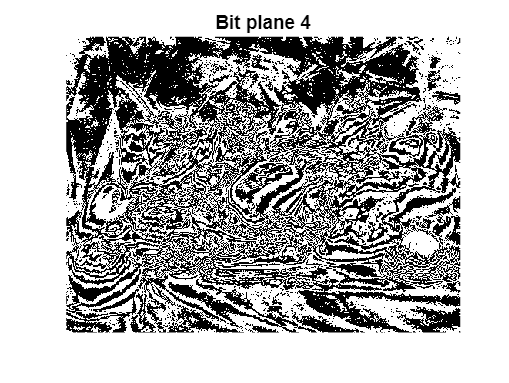

B=bitget(Igrey,4); figure, imshow(logical(B));title('Bit plane 4');

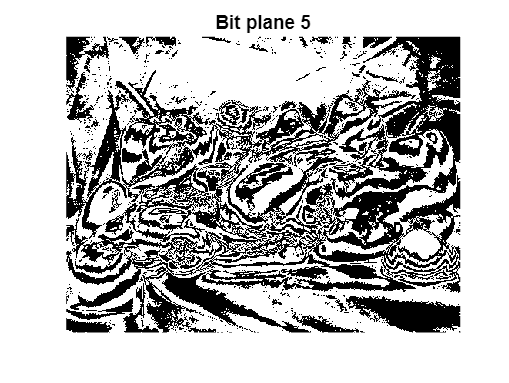

B=bitget(Igrey,5); figure, imshow(logical(B));title('Bit plane 5');

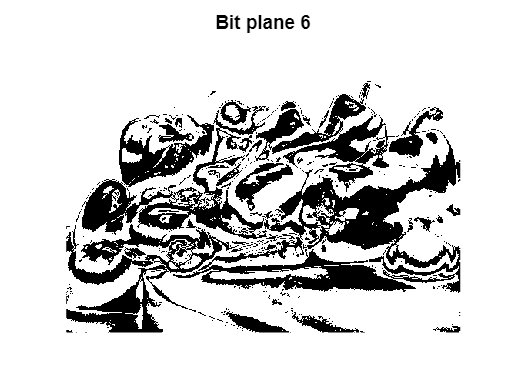

B=bitget(Igrey,6); figure, imshow(logical(B));title('Bit plane 6');

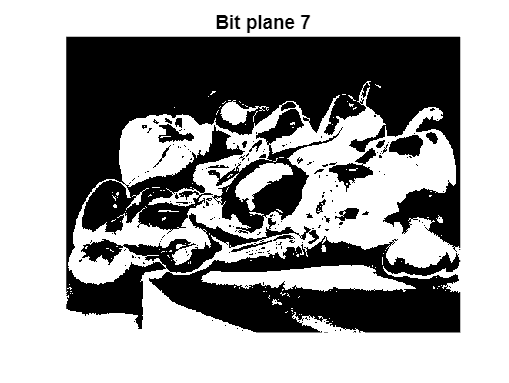

B=bitget(Igrey,7); figure, imshow(logical(B));title('Bit plane 7');

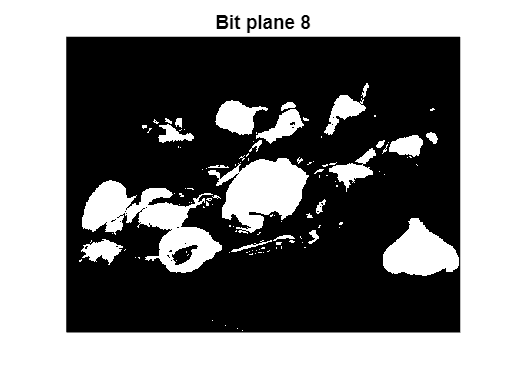

B=bitget(Igrey,8); figure, imshow(logical(B));title('Bit plane 8');

Mean Filter

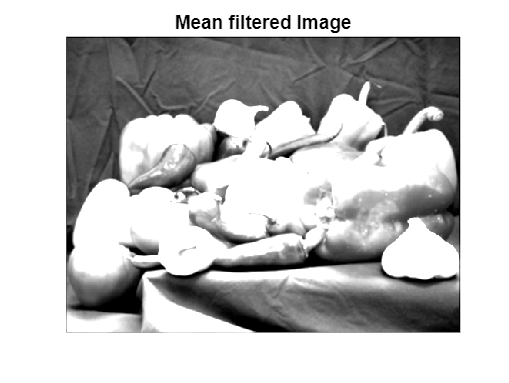

h = fspecial('average', 3);
Imean=filter2(h, Igrey);
imshow(Imean,[30,90])
title('Mean filtered Image')

Median Filter

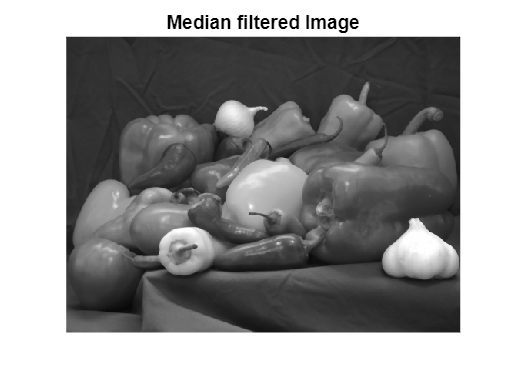

Imed = medfilt2( Igrey , [3 3] ) ;
imshow(Imed)
title('Median filtered Image')

Edge Detection using Sobel operator

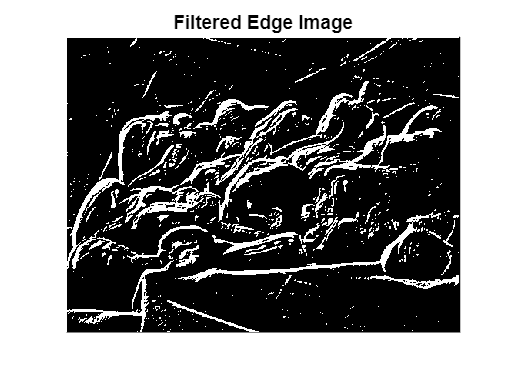

% Sobel Operator Mask
Mx = [-1 0 1; -2 0 2; -1 0 1];
My = [-1 -2 -1; 0 0 0; 1 2 1];
Ix=filter2(Mx, Igrey);
Iy=filter2(My, Igrey);
Iedge=Ix+Iy;
th=25;
imshow(Iedge>th)
title('Filtered Edge Image')